
% data preprocess
data = readtable('Results_21Mar2022.csv');
disp(['Data type of data: ', class(data)]);

Data type of data: table


data.mc_run_id = [];
format long g;

numericData = data(:, 2:10);   
nParticipants = data.n_participants;  
stringData = data(:, 21:23);  

% new table
result = table('Size', [0 13], ...
    'VariableTypes', {'cell','double', 'double', 'double', 'double', 'double', 'double', 'double', 'double', 'double','cell','cell','cell'},...
                        'VariableNames', {'Group', 'mean_ghgs', 'mean_land', 'mean_watscar', ...
                                         'mean_eut', 'mean_ghgs_ch4', 'mean_ghgs_n2o', ...
                                         'mean_bio', 'mean_watuse', 'mean_acid', ...
                                         'sex', 'diet_group', 'age_group'});
uniqueGroups = unique(data.grouping);  
% average
for i = 1:length(uniqueGroups)
    group = uniqueGroups{i};  
    %disp(['Data type of group: ', class(group)]);
    idx = strcmp(data.grouping, group);
    
    groupNumericData = numericData(idx, :);
    groupParticipants = nParticipants(idx);
   
    weights = repmat(groupParticipants, 1, width(groupNumericData));
    weightedAverage = sum(table2array(groupNumericData) .* weights, 1) / sum(groupParticipants);
    %disp(['Data type of weightedAverage: ', class(weightedAverage)]);

    modeStrings = arrayfun(@(col) modeString(stringData{idx, col}), 1:width(stringData), 'UniformOutput', false);
    %disp(['Data type of modeStrings: ', class(modeStrings)]);
    
    columnNames = result.Properties.VariableNames;
    weightedAverageRow = array2table(weightedAverage, 'VariableNames', columnNames(2:10));
    modeStringsRow = array2table(modeStrings, 'VariableNames', columnNames(11:13));
    groupTable = table({group}, 'VariableNames', {'Group'});
    
    newRow = [groupTable, weightedAverageRow,modeStringsRow];   
    result = [result; newRow];
end

disp(result);

             Group                 mean_ghgs           mean_land         mean_watscar          mean_eut          mean_ghgs_ch4        mean_ghgs_n2o          mean_bio          mean_watuse          mean_acid          sex       diet_group    age_group
    ________________________    ________________    ________________    _______________    ________________    _________________    _________________    ________________    ________________    ________________    ________    __________    _________

    'fish_female_20-29'           4.902947125081    6.48903080688201    17131.963351906      20.98546417884       0.842863531942       0.322486106938     248.13521166088    759.237210568599      22.77095614381    'female'    'fish'         '20-29' 
    'fish_female_30-39'           4.942664483793    6.51588625901501    17652.628539581      20.94844234705    0.836500414363999       0.321970771612     249.82768412553    759.629613210799      23.25777137329    'female'    'fish'         '30-39' 
   

tbl=result(:,[2:13]);
tbl.diet_group= categorical(tbl.diet_group);

p=parallelplot(tbl)

p =   ParallelCoordinatesPlot - 属性:

            SourceTable: [72×12 table]
    CoordinateVariables: {'mean_ghgs'  'mean_land'  'mean_watscar'  'mean_eut'  'mean_ghgs_ch4'  'mean_ghgs_n2o'  'mean_bio'  'mean_watuse'  'mean_acid'  'sex'  'diet_group'  'age_group'}
          GroupVariable: ''

  显示 所有属性


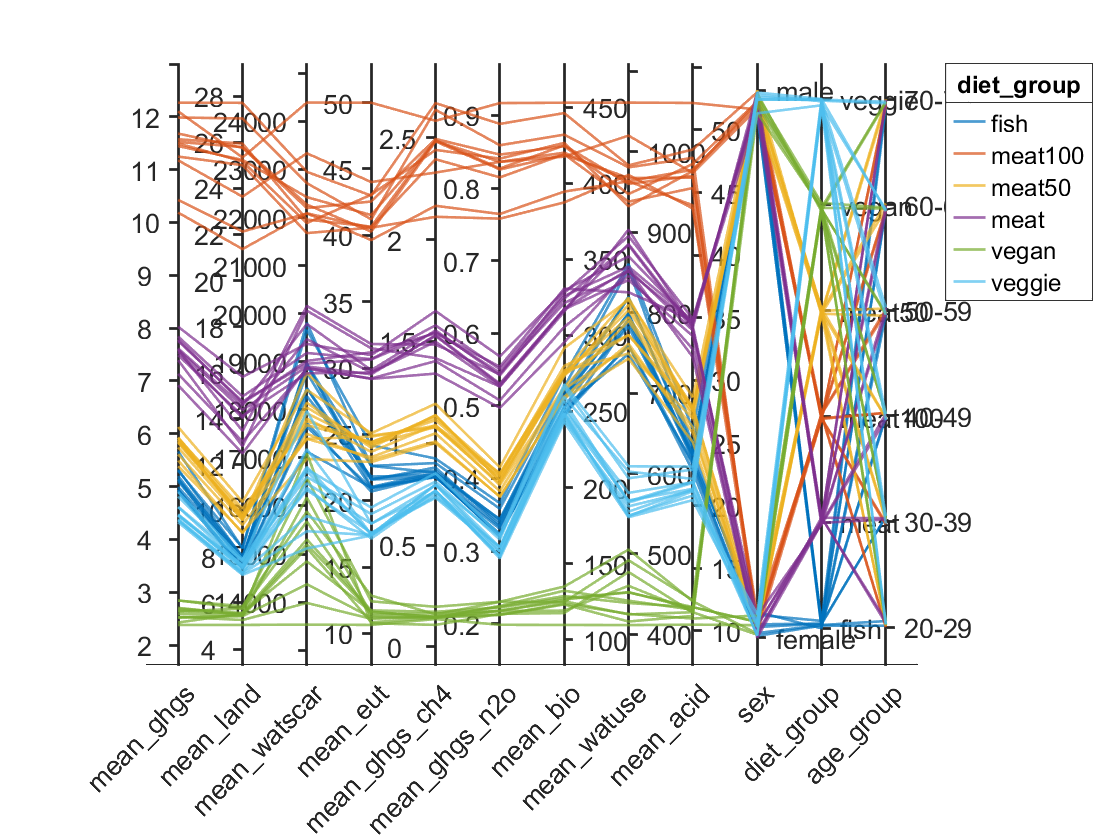

p.GroupVariable = 'diet_group';


%p1=parallelplot(tbl)
%p1.GroupVariable = 'sex';

%p2=parallelplot(tbl)
%p2.GroupVariable = 'age_group';


function result = modeString(strArray)
    if isempty(strArray)
        result = '';
    else
        [uniStr, ~, idx] = unique(strArray);
        freq = accumarray(idx, 1);
        result = uniStr{find(freq == max(freq), 1, 'first')};
    end
end

